clc; clearvars;

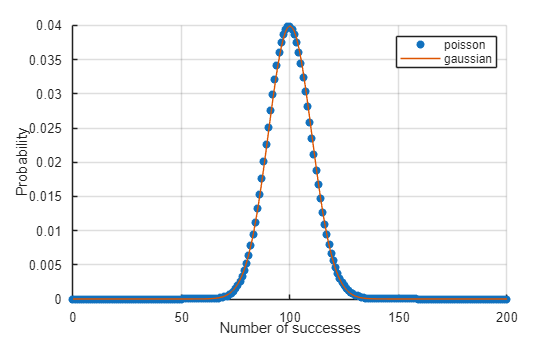

a = 100;

start_i = 0;
end_i = 2*a;
n = linspace(start_i,end_i,1e3);
n_int = start_i:end_i;


poiss_STD = sqrt(a);
pois_f = poisspdf(n_int,a);
gauss_f = normpdf(n,a,poiss_STD);

figure;
hold on
scatter(n_int,pois_f,'filled','DisplayName',"poisson")
plot(n,gauss_f,'DisplayName',"gaussian")

hold off
xlabel("Number of successes")
ylabel("Probability")
grid on
legend

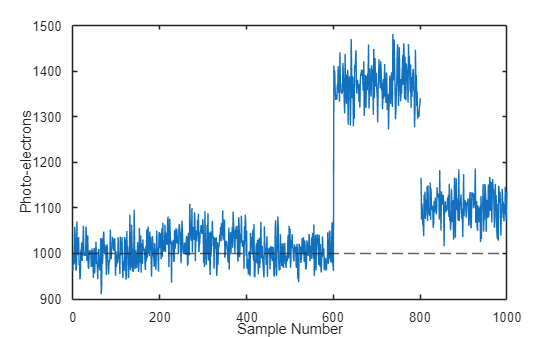

nB = 1000;
SNR = 10;

xi = 0:1000;
ns = NaN(1,length(xi));

ns(0+1:200+1) = 0;
ns(201+1:400+1) = 32;
ns(401+1:600+1) = 0;
ns(601+1:800+1) = 370;
ns(801+1+1:1000+1) = 100;

n = normrnd(ns+nB,sqrt(ns+nB));

figure;
plot(xi,n)
xlabel("Sample Number")
ylabel("Photo-electrons")
yline(nB,'--')


roots([1 -(SNR.^2) -(SNR.^2)*nB])

ans =   370.1562
 -270.1562


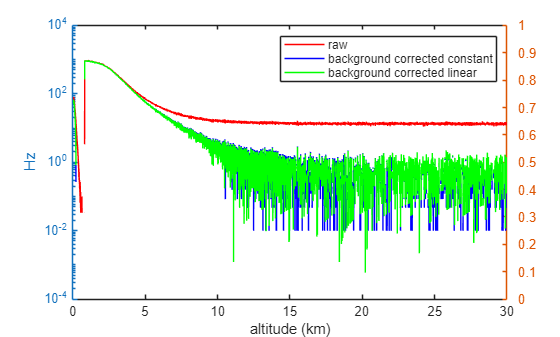

addpath(genpath("C:\Users\tely1\OneDrive - The City College of New York\Matlab Onedrive\O3_Lidar\proc_functions"))
dataPath = "C:\Users\tely1\OneDrive - The City College of New York\Matlab Onedrive\o3_lidar_data\20220720";

data_format     = "bin";
prefix = "xy";

[scaled_data,times,configs] = read_lidar_datafiles(dataPath,data_format,prefix);
scaled_data = scaled_data(1:8000,:,:,:);

times = times(:,2);
% times.TimeZone = "UTC";

num_bins = size(scaled_data,1);
num_files = size(scaled_data,2);
num_devices = size(scaled_data,3);

dz = 3.75;
h = (dz.*(1:num_bins))';
hkm = h./1000;

id = 1;
TR = 2;

td = 270;
data_an = scaled_data(:,:,TR,1);
data_pc = scaled_data(:,:,TR,2);
data_pc = data_pc./(1-data_pc/td);
% data_pc = movmean(data_pc,100,1);

bg_bins = 4000:8000;

B_an = rm_bk(data_an,h,bg_bins,'const');

B_pc_const = rm_bk(data_pc,h,bg_bins,'const');
B_pc_lin = rm_bk(data_pc,h,bg_bins,'linear');

an = data_an - B_an;
pc = data_pc - B_pc_const;
pc2 = data_pc - B_pc_lin;

nPC = pc;
nbg = B_pc_const;


figure;

yyaxis left
semilogy(hkm,data_pc(:,id),'r','DisplayName','raw')
hold on
plot(hkm,pc(:,id),'b-','DisplayName', 'background corrected constant')
plot(hkm,pc2(:,id),'g-','DisplayName', 'background corrected linear')

hold off
xlabel('altitude (km)')
ylabel('MHz')
legend

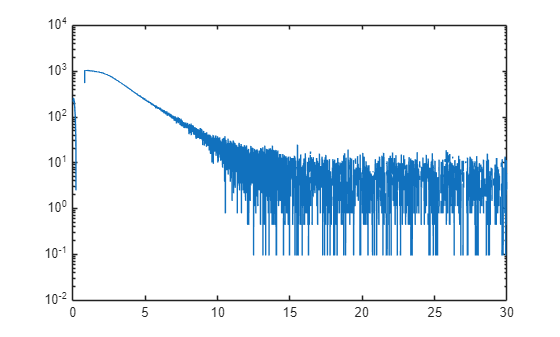


% yyaxis right

figure
semilogy(hkm,snrFunc(1200,nPC(:,id),nbg(:,id)))

function snr = snrFunc(M,ns,nB,nD)
    arguments
        M double
        ns double       % average signal counts
        nB double = 0   % average background counts
        nD double = 0   % average dark counts
    end

    snr =sqrt(M) * ns ./ sqrt(ns + nB + nD);
end

function bg = rm_bk(data,z,bins,mode)
    temp_data = data(bins,:);
    temp_z = z(bins);

    [n_rows,n_cols] = size(data);

    switch mode
        case "const"
            bg = mean(temp_data,1,"omitmissing");
            bg = repmat(bg,n_rows,1);

        case "linear"
            bg = NaN(size(data));

            for i = 1:n_cols
                p = polyfit(temp_z,temp_data(:,i),1);
                bg(:,i) = polyval(p,z);
            end
    end
end